# Modelo de estación con piezas estáticas

Dificultad: Normal (Básico) 

## General

- Se genera una estación con las piezas estáticas.

- Se dispone de un subsistema de Simulink con mascara para definir cada elemento del sistema

- Los elementos tienen asociado uno o varios ficheros *stl*, y las propiedades dinámicas (masas, cdg, momentos).

- Los objetos de la clase $Pieza$ guardan esa información y es la variable de entrada del subsistema (mascara).

- Las piezas estáticas va a ser objetos de trabajo (tablero de ajedrez), del robot o cargas (piezas de ajedrez) del mismo.

## Iconos de la Librería SimRobot

- Se dispone de clases de iconos para crear estaciones, los iconos de trabajo, los de robot y otros elementos.

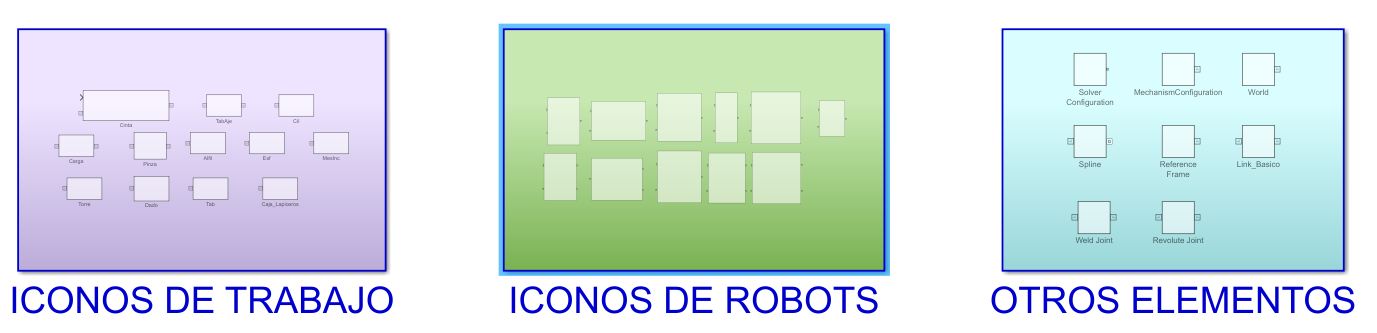

### Iconos de trabajo

- Los iconos estáticos tienen asociadas propiedades gráficas, de posición y dinámicas definidas en la clase $Pieza$, ver más adelante.

- El icono tiene una máscara que pregunta por una variable tipo $Pieza$ asociada al icono.

- La mayoría de los iconos son variables, por lo que todas sus propiedades pueden cambiar, gráficas, posición y propiedades dinámicas.

- Solo los iconos con más de una gráfica asociada tienen que ser definidos de forma constante dentro del icono, por ejemplo, el tablero de ajedrez.  

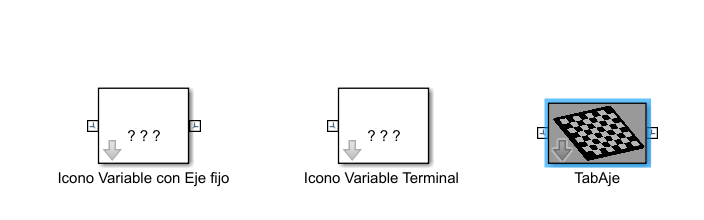

### Iconos de robots

- Se dispone de diferentes modelos de robot obtenidos de la conversión de los modelos de robot en formato URDF (Universal Robot Defined Format) a formato SimScape.

- Los robots tienen entrada de posición *Multbody* y de señal para el movimiento de sus articulaciones.

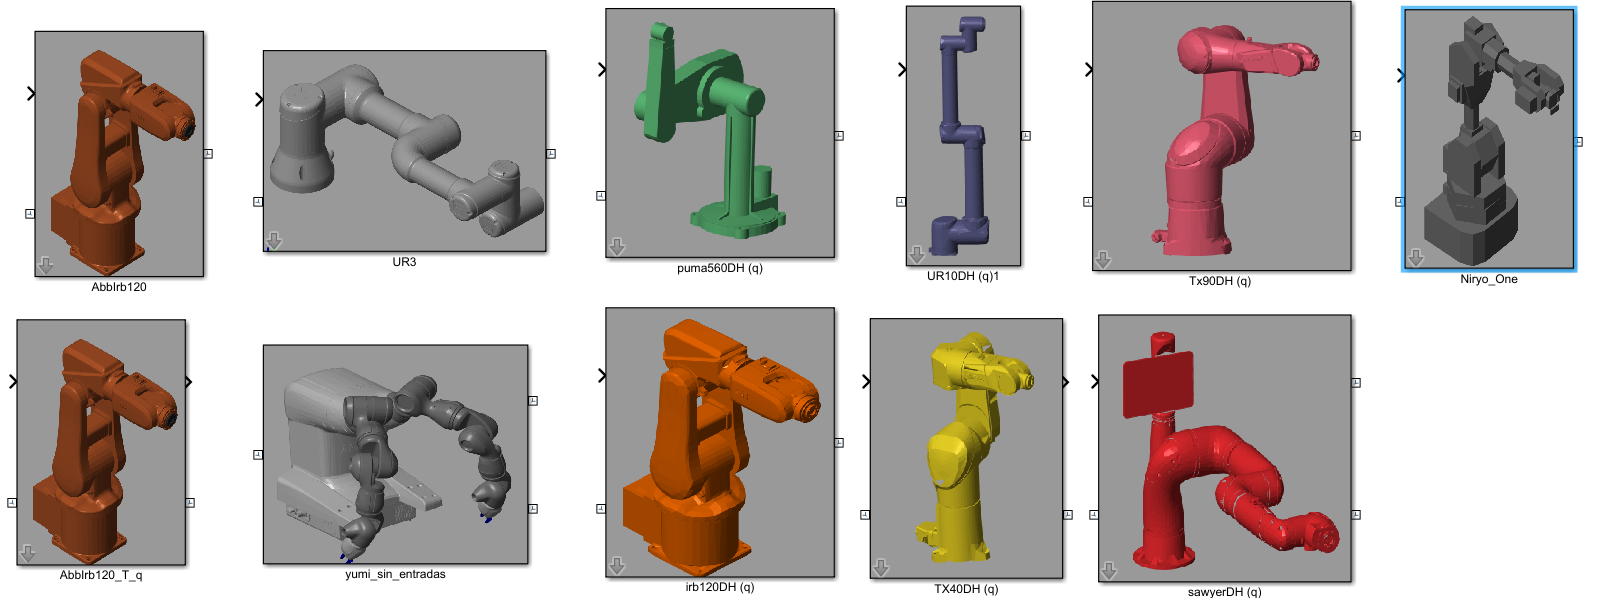

### Iconos de control

- Solver: Es la configuración del algoritmo de simulación propio de Multibody.

- Configuración: Parámetros generales de gravedad.

- Ejes globales y relativos.

- Iconos de subsistemas.

- Articulaciones fijas, rotacionales y prismáticas.

- Rastreador (Spline): Interpola en la simulación puntos para representar la trayectoria del TCP.

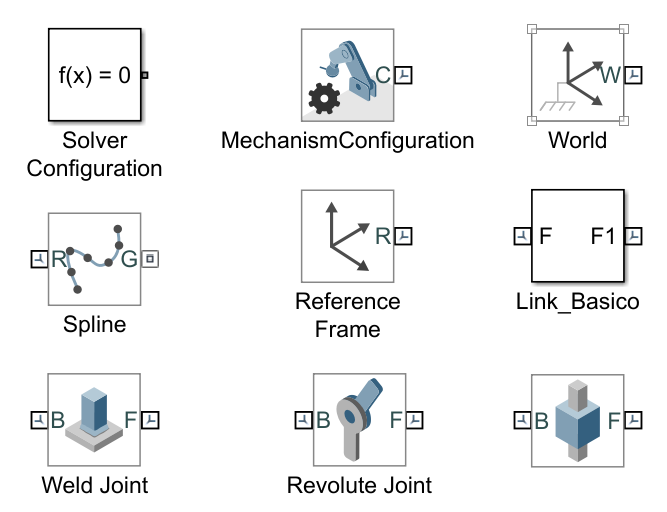

## Modelo del sistema estático

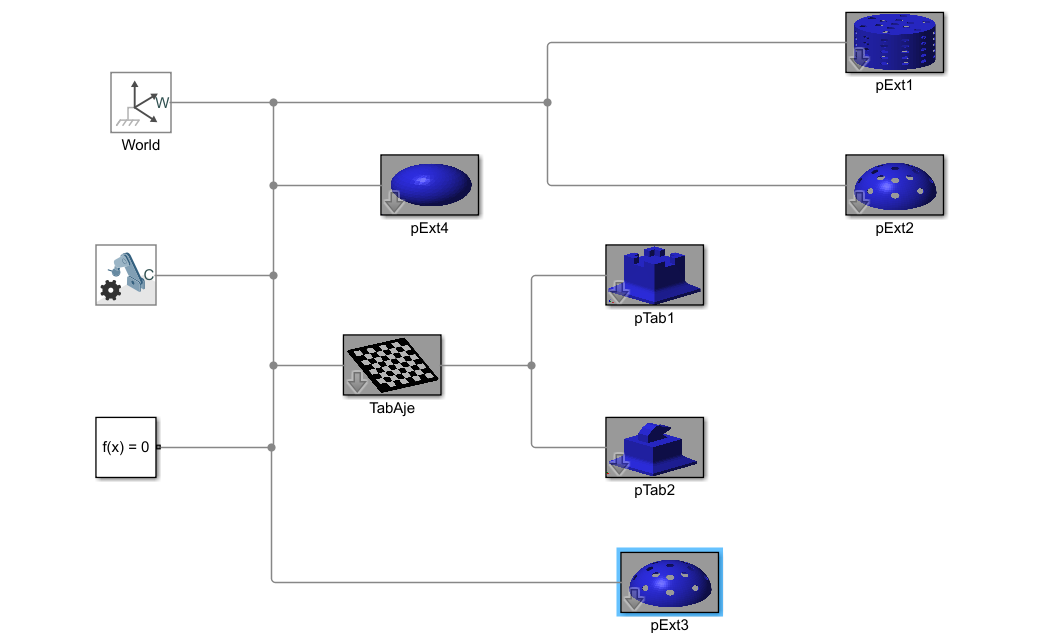

#### **Elementos de control de SimScape:** 

- **Solver** es el algoritmo para resolver la simulación 

- **Configuración general** para definir parámetros generales como gravedad, 

- **Eje global** del sistema mecánico.

- **Hilos:** Los hilos de SimScape Multibody representan las posiciones relativas de cada uno de los componentes respecto al icono anterior o base.

#### Iconos estáticos de entrada-salida y terminales.

- Esferas ($pExt1$*, *$pExt2$), Cilindro ($pExt3$), Tablero ($TabAje$*), *pieza nula ($pExt3$) dependen de la base.

- Torre ($pTab1$) y Caballo ( $pTab2$) dependen del tablero.

- Tablero es un icono estático, no van a cambiar de fichero *stl.*

- Torre exterior, caballo y torre interior van a ser variables, ya que se puede cambiar uno por otro.

- En el momento de partida, torre exterior es nulo, y la torre está en el icono torre interior.

## Ejemplo de tablero de ajedrez

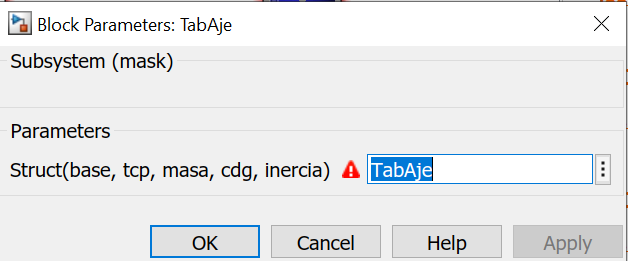

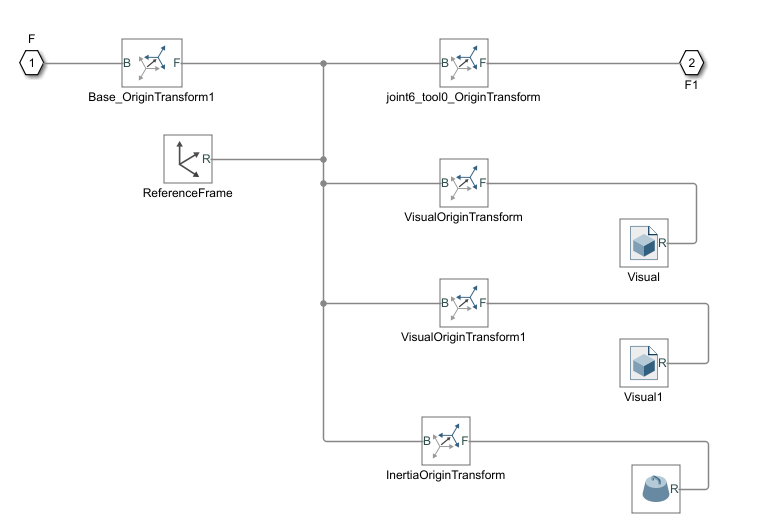

- El icono tiene una máscara con una variable de entrada tipo objeto $Pieza$.

- Dentro del icono están las referencias desde la entrada a los fichero/s *stl* y desde los fichero/s *stl* a las salidas salida, con todas sus propiedades definidas a partir del objeto $Pieza$.

- Dentro del icono están las propiedades dinámicas (masa, cdg, momentos de inercia) del icono también definidas en el objeto $Pieza$.

- Si los ficheros *stl* del icono son constantes, se modelan directamente desde el directorio *Biblioteca*.

### Clase Pieza $obj= Pieza('fichero')$                                             

- $obj$: Variable con las propiedades gráficas e inerciales del icono. 

- $fichero$: Es el nombre (cadena de caracteres) del fichero *stl* que forma parte del icono. Debe ser un fichero del directorio *Biblioteca*.

### Propiedades del objeto $obj$

- $obj.base$:  Posición de la base del objeto, formato $[[x,y,z]m, [R_z,R_y,Rx]rad]$.

- $obj.tcp$: Posición de salida del objeto para iconos entrada-salida.

- $obj.masa$, $obj.cdg$, $obj.inercia$: Propiedades dinámicas del objeto, masa, centro de gravedad, matriz de inercia.

- $obj.color$: Color y opacidad del objeto, formato $[r,g,b,opaco]$, valores de $0-1$ para el rojo, verde, azul y la opacidad.

- $obj.nombre$: Nombre de los ficheros gráficos asociados, *'*.stl'* para simular y* '*.png'* para la máscara. Deben estar definidos en el directorio *Biblioteca*.

### Funciones asociadas

- $obj.Base()$, $obj.Tcp()$, $obj.Din()$, $obj.Color()$ : Modifica el valor de la base, TCP, dinámica y color del objeto.

- $obj.PegarEn()$: Ver después. Cambia las piezas de icono.

## Funciones asociadas 

- $[H,pose]= Prod(obj1,obj2)$: Multiplica el objeto $var1$ por el objeto $var2$, devolviendo la matriz homogénea correspondiente.  Si solo tiene un argumento, devuelve en formato matriz homogénea $H$, o $pose=[[x,y,z]m,[R_z,R_y,R_x]rad]$  la información del objeto dado.

- Los objetos $obj1$ y $obj2$ pueden ser matriz homogénea $(4\times 4)$, vector Euler $pose= [[x,y,z]m,[R_z,R_y,R_x]rad]$, vector $pos=[x,y,z]m$,  objeto *Pieza* (se toma la propiedad $Pieza.tcp$), y objeto *Cin*, robots (se toma el TCP del robot).

- $[H,pose]= Prod(x1,x2, y1)$: Devuelve la matriz homogénea y el vector Euler de tres puntos $x1$, $x2$ y $y1$.

- $[pose]= ProdV(obj1,pose)$ está pensada para modificar los elementos $pose$ de la matriz de entrada multiplicándolos por el objeto $obj1$. La salida es otra matriz $pose$.

## Inicialización de variables de la estación

clear all
% Conversor a radianes
deg= pi/180;

Estacion= 'C06S1_Piezas_Estaticas.slx';

% Objetos de trabajo cosntantes. No se van a mover del icono y los figuras
% stl están definidas dentro de él.

% Pieza fija, no se pretende mover en el programa
% Los ficheros stl están definidos de forma constante en el icono.
TabAje= Pieza();
% Se mueve la base [[x,y,z]m,[Rz,Ry,Rx]rad]
TabAje.Base([[300, -100, 100]*1e-3, [0,0,0]*deg]);
% La salida se ajusta a la primera casilla 
TabAje.Tcp([[25,25,7]*1e-3,[0,0,0]*deg]);
TabAje.Color([0.3,0.3,0.3,0.7]);

% Pieza variable, se puede mover en el programa
pExt1= Pieza('Cilindro');
pExt1.Base([[0, 500, 200]*1e-3, [0,0,0]*deg])
pExt1.Color([0.2,0.4,0.6,0.7])


pTab1= Pieza('Torre');
Px= 1; Py= 1;
pTab1.Base([[50*Px, 50*Py,0]*1e-3, [0,0,0]*deg])
pTab1.Color([1,1,1,1]);

pTab2= Pieza('Caballo');
Px= 3; Py= 5;
pTab2.Base([[50*Px, 50*Py, 0]*1e-3, [0,0,0]*deg])
pTab2.Color([0,0,0,1]);

pExt2= Pieza('Esfera');
pExt2.Base([[0,-300,200]*1e-3, [0,0,0]*deg]);
pExt2.Color([0.5, 0.4, 0.2, 0.7]);

% Posición relativa a la primera esfera
pExt3= Pieza('Esfera');
pExt3.Base([[0,0,0]*1e-3, [0,0,180]*deg], pExt2);
pExt3.Color([0.3, 0.7, 0.2, 0.7]);

% Variable comodín
pExt4= Pieza('Null');
% pExt4= Pieza(); % por defecto

open_system(Estacion)

sim(Estacion, 1);

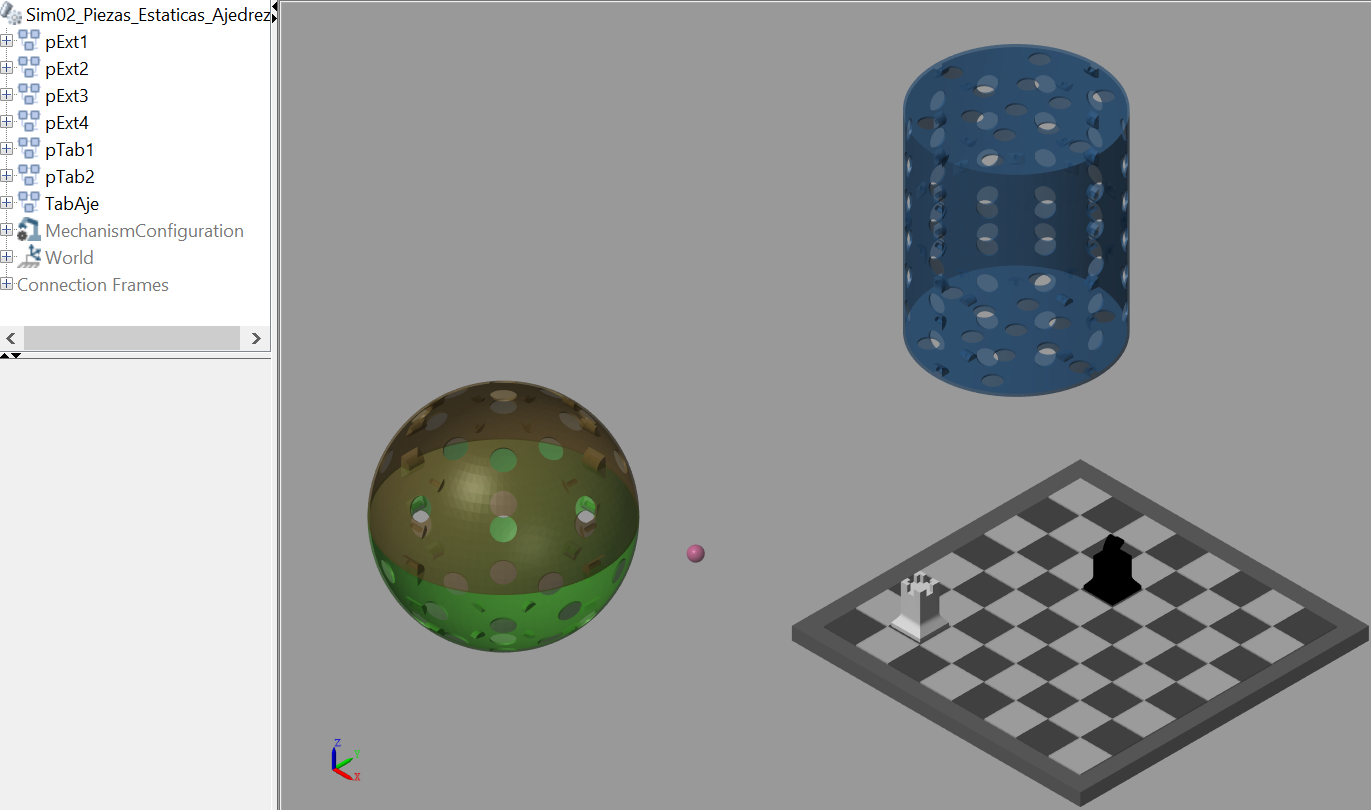

## Mover piezas y Null con appMover

- La app appMover mueve las piezas de sitio.

- Introducir en *Estación* el nombre del fichero Simulink

- Introducir en *Cin/Pieza* el nombre de la pieza.

- Mover la pieza respecto del origen en $[x,y,z,R_z,Ry,R_x]$.

- Introducir en *Wobj(Tool)* una pieza de referencia.

- Los movimientos $[x,y,z,R_z,Ry,R_x]$ se realizarán respecto a dicha referencia.

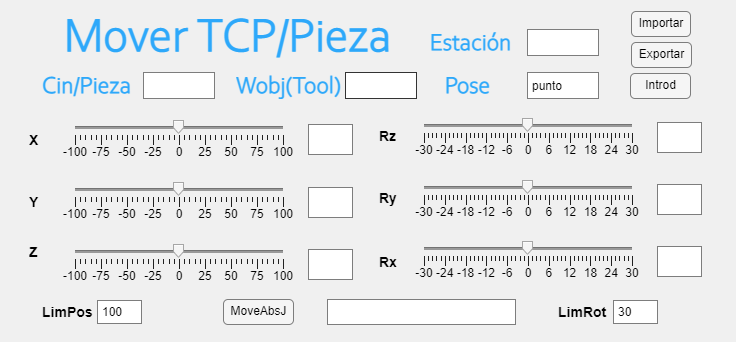

appMover

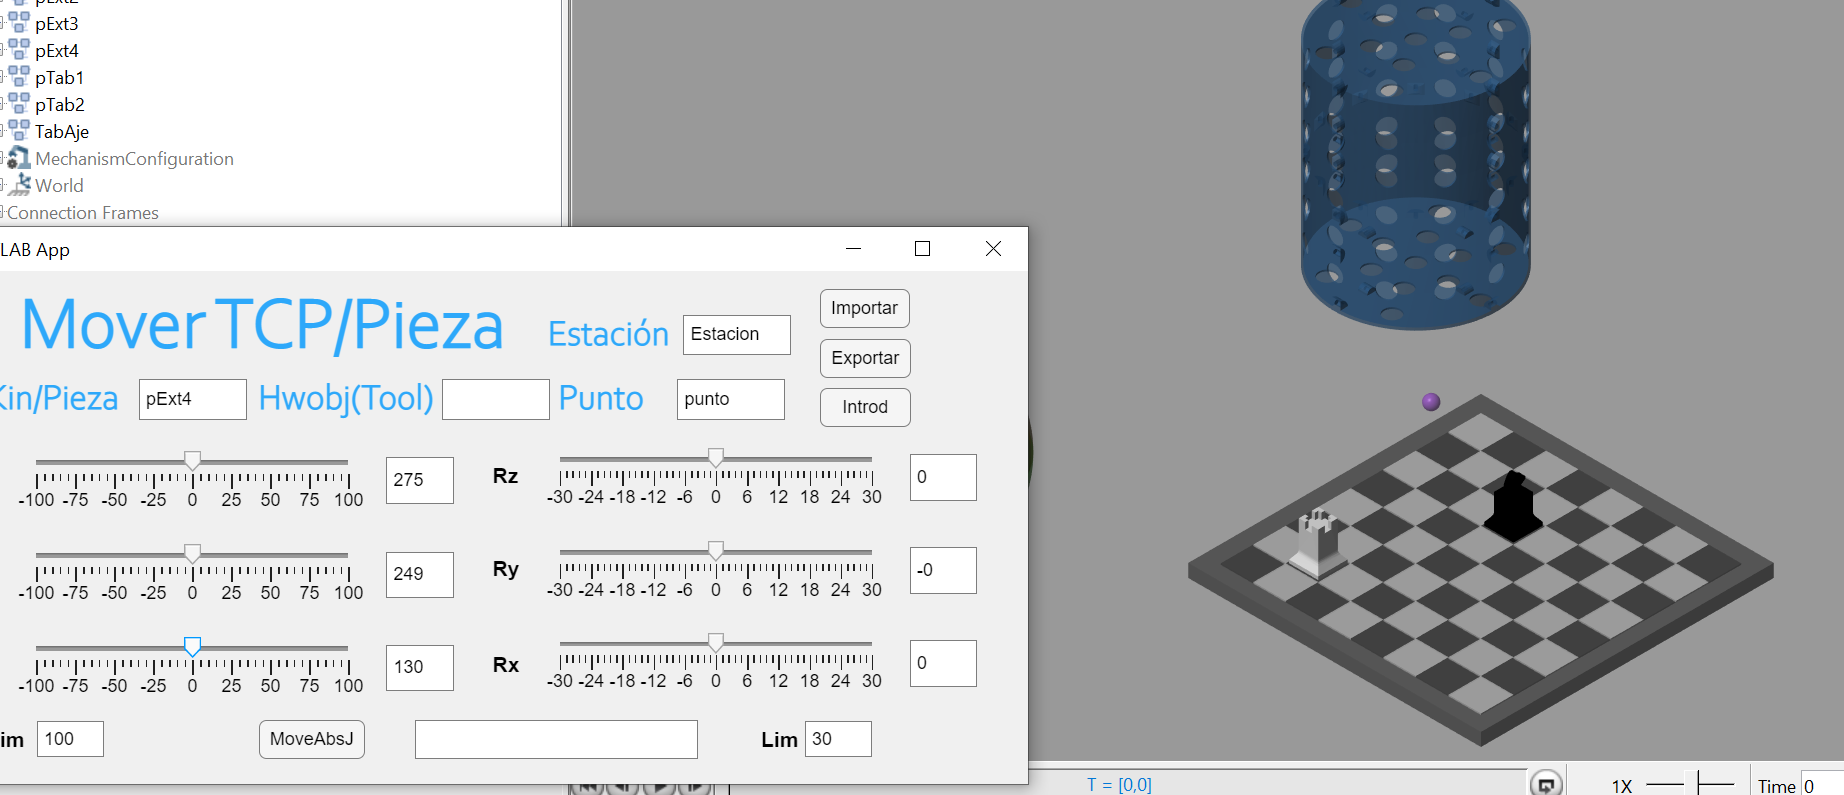

## Método $Pieza.PegarEn(load_1,load_2,ref_1,ref_2)$

- Copia las propiedades del objeto $load_2$ en $load_1$.

- Los argumentos $ref_1$ y $ref_2$ son los objetos $Pieza$ o las matrices homogéneas de las referencias asociadas a $load_1$ y $load_2$ respectivamente. Si un objeto tiene como referencia la referencia global se puede poner por defecto un argumento nulo $[]$. 

- El método modifica la posición de la pieza en $load_1$ de forma que la pieza que había en $load_2$ y ahora está en $load_1$ no cambie de posición respecto a la referencia global.

- El icono $load_2$ se pone como objeto nulo, es decir, esfera de radio muy pequeño. 

## Mover torre de icono interior de Torre a icono exterior de Torre

- Se pega la torre interior en el icono de torre exterior, pero en la simulación no se nota, ya que se modifica su posición de forma que su valor con respecto a la referencia global no varíe.

- Ver como el icono $pTab1$ ha pasado a ser nulo, y el icono $pExt4$ ha pasado a contener la torre.

- Ver que aparentemente la figura mostrada es igual antes y después del cambio.

%PegarEn(pExt4, pTab1, [], TabAje.Htcp)
PegarEn(pExt4, pTab1, [], TabAje)
sim(Estacion, 1);

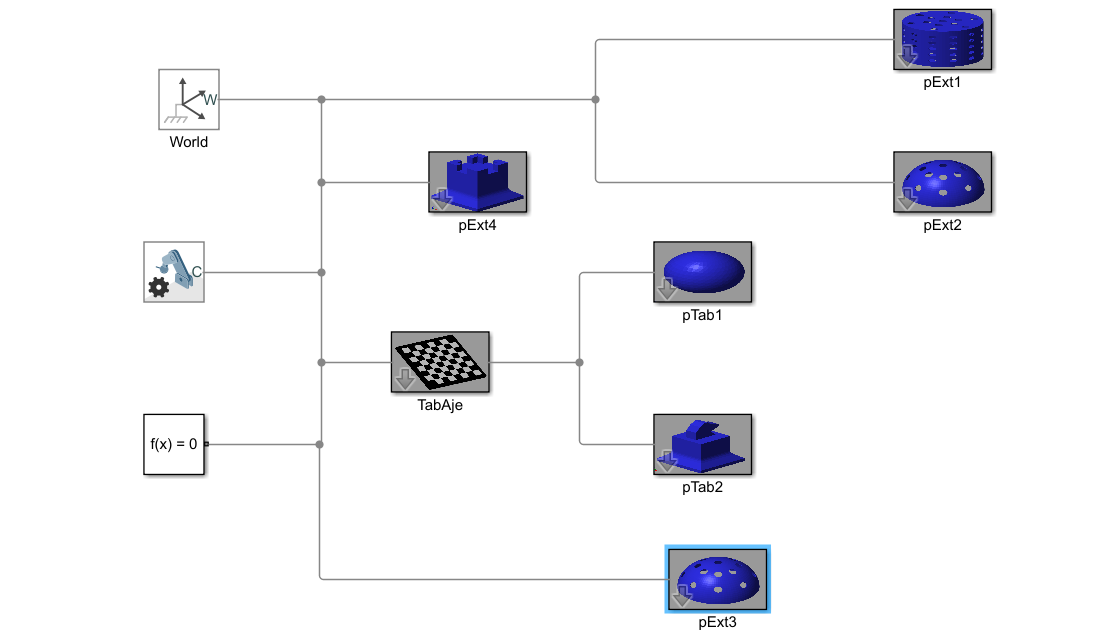

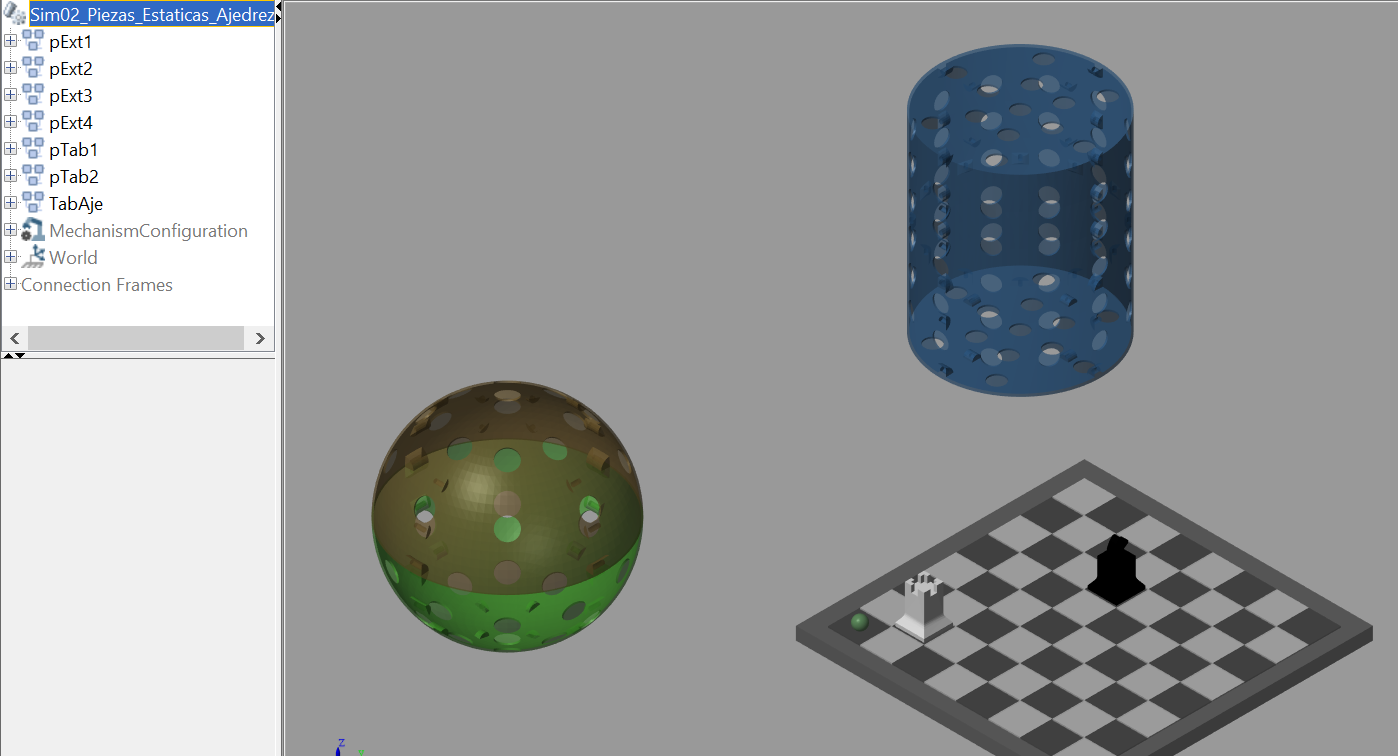

## Mover tablero con caballo, pero sin torre

- Al mover la mesa se mueve el caballo, pero no la torre ya que pertenece al icono exterior.

TabAje.Base([[100, -100, 100]*1e-3, [0,0,0]*deg]);
% Simular la estación estática durante un tiempo

sim(Estacion, 1);

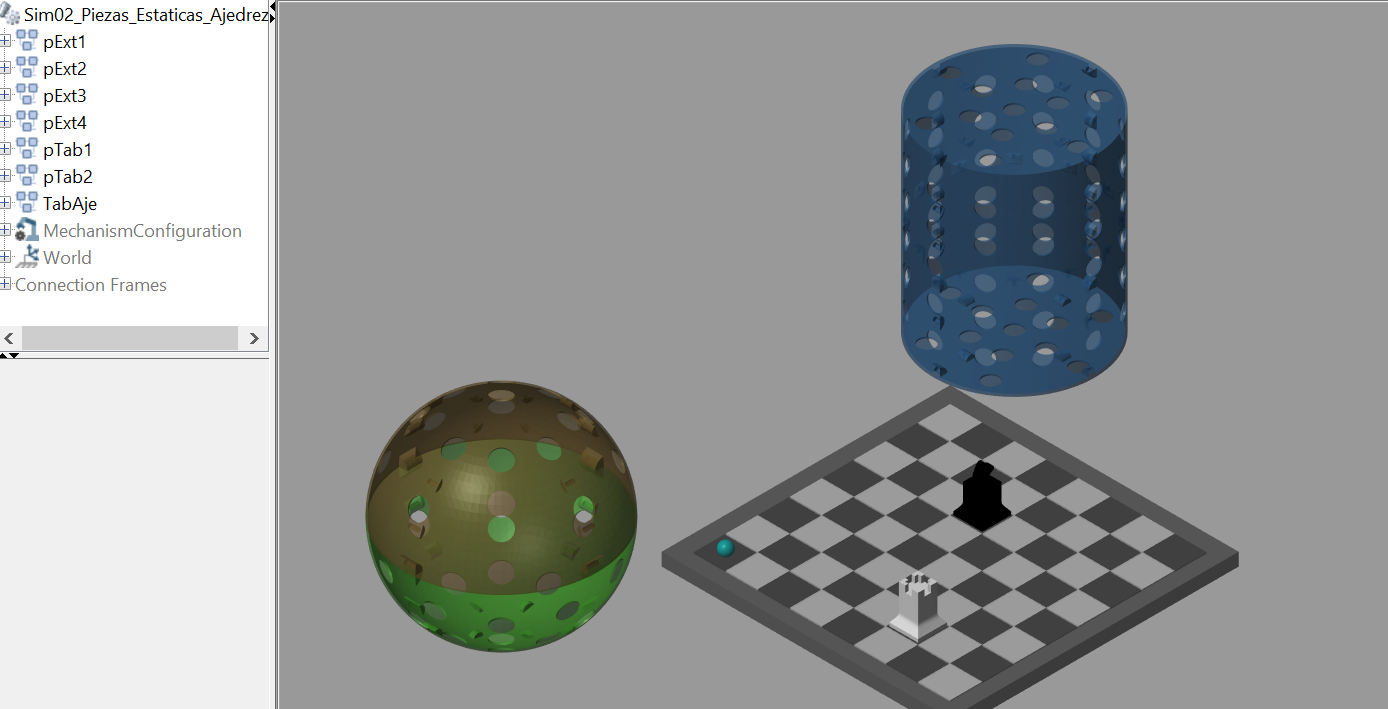

- Mover la esfera de $pExt2$ a la parte de arriba del cilindro y luego a la de abajo girada $180^o$.

pExt2.Base([[0, 0, 100]*1e-3, [0,0,0]*deg], pExt1);

% Simular la estación estática durante un tiempo
% Moverlo a la parte de abajo y girar de otra forma

pExt2.Base(Prod(pExt1, [[0, 0, -100]*1e-3, [0,0,180]*deg]));

sim(Estacion, 1);

## Posición inicial de las piezas. Método de los tres puntos

- Cuando se crea una pieza con un programa CAD se puede hacer en el origen o en otra parte cualquiera del espacio.

- Si la pieza está creada en el origen es muy sencillo trabajar con ella o moverla.

- Si la pieza está creada fuera del origen es preciso calcular su eje por medio del método de los tres puntos, dos puntos en el eje $x$, $x1$ y $x2$ y un tercero en el eje $y$, $y1$, que definen un eje en el espacio.

clear all
% Conversor a radianes
deg= pi/180;

Estacion= 'C06S2_Piezas_Fuera_Origen.slx';


% Objeto de trabajo
Tab= Pieza('Tablero');
Tab.Base([[0, 200, 100]*1e-3, [0, 0, 30]*deg]);
Tab.Color([0.2, 0.5, 0.1, 0.7])


% Icono fijo
% Mesa inclinada. Sus puntos están en una posición indeterminada respecto
% del origen. Es preciso usar la regla de los tres puntos para fijarlos
MesInc= Pieza('MesaInclinada');
MesInc.Base([[0, 0, 0]*1e-3, [0, 0, 0]*deg]);
% Ejes de la mesa por 3 puntos
% Puntos para definir los ejes de la mesa
x1= [0.4000, 0.1330, 0];
x2= [0.1500, -0.3000, 0];
y1= [0.7232, -0.0536, 0.1000];
MesInc.Tcp(Prod(x1,x2,y1));

MesInc.Color([0.3, 0.8, 0.2, 0.7]);


Botella= Pieza('Botella');
Botella.Base([[0,0,0]*1e-3, [0,0,0]*deg]);
Botella.Tcp(Prod([[45,0,45]*1e-3,[0,0,-90]*deg]))
Botella.Color([0,0.3,0.8,0.7]);


% Objeto de trabajo nulo en el origen para ver la posición de los otros
pExt= Pieza('Null');
pExt.Base([[0,0,0]*1e-3, [0,0,0]*deg]);
pExt.Color([1,0,0,1]);

open_system(Estacion);
sim(Estacion,1);

### Ir con Null a los ejes de los objetos

- El tablero ha sido creado en el origen. Moverlo es sencillo.

- La mesa inclinada ha sido creada fuera del origen y hay que buscar su eje por 3 puntos

- La botella ha sido creada fuera del origen y hay que ver su eje a "mano".

- Usar para ello la appMover

pExt.Base(Tab);
sim(Estacion,1);
pause(2)
pExt.Base(MesInc);
sim(Estacion,1);
pause(2)
pExt.Base(Botella);
sim(Estacion,1);

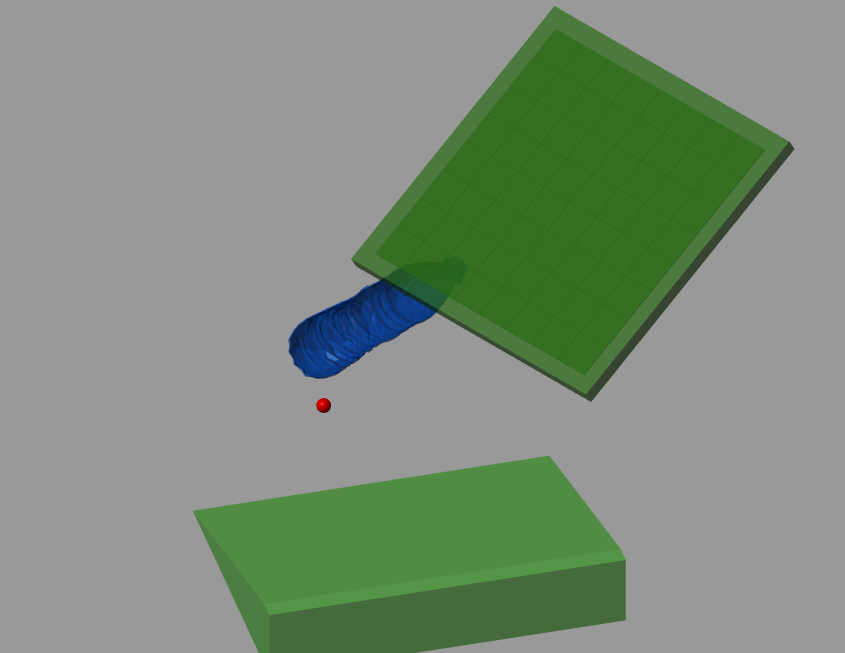

### Abrir appMover

- Definir el nombre de la estación.

- Definir el objeto que se quiere mover (en este caso $pExt$)

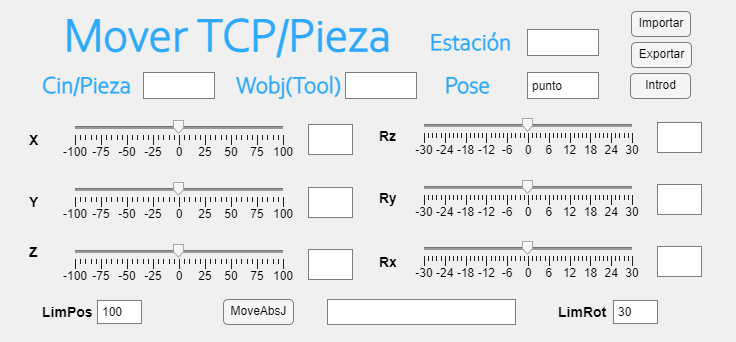

appMover